## Лабораторная работа 10

## Пример 1.

Интерактивное задание и отображение точки на плоскости.

Следующий код подготавливает систему координат, задает и отображает точку на плоскости. Для интерактивного задания точки на плоскости используется функция ginput.

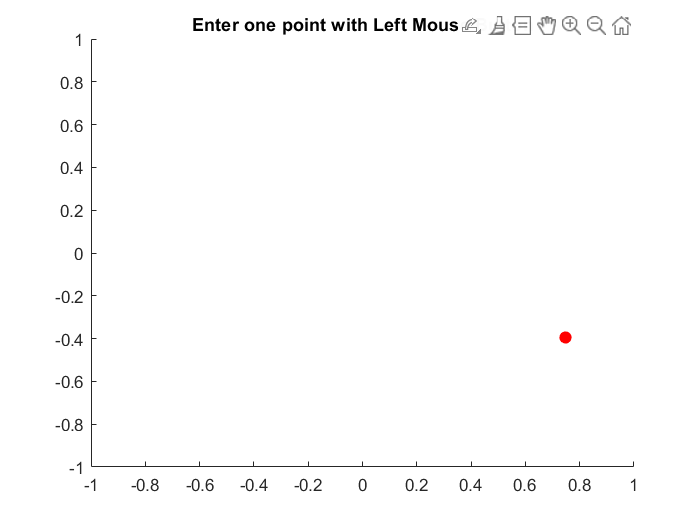

clf
axis([-1 1 -1 1])
title('Enter one point with Left Mouse Button')
hold on
A = ginput(1);
plot(A(1), A(2), '.r', 'MarkerSize', 25)

## Пример 2.

Следующий код подготавливает систему координат, задает и отображает отрезок на плоскости.

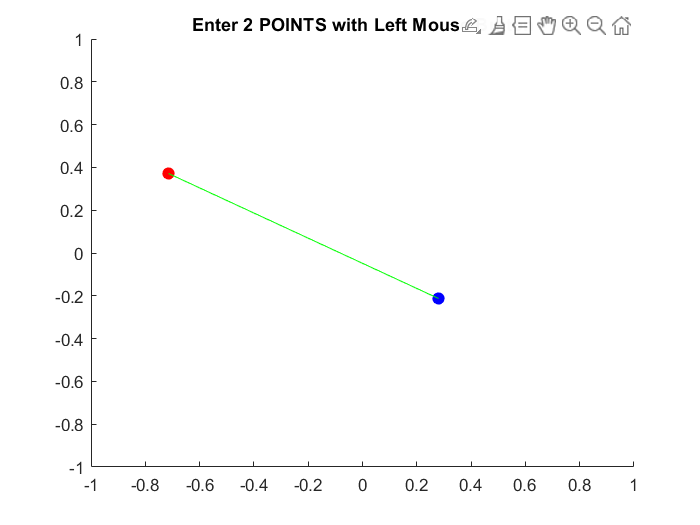

clf % clear figure
axis([-1 1 -1 1])
title('Enter 2 POINTS with Left Mouse Button')
hold on
A = ginput(1);
plot(A(1), A(2), '.r', 'MarkerSize', 25)
B = ginput(1);
plot(B(1), B(2), '.b', 'MarkerSize', 25)
plot([A(1), B(1)], [A(2), B(2)], 'g')

## Пример 3. 

Движение точки по прямой с использованием линейного твининга.

Следующий код подготавливает систему координат, задает и отображает отрезок на плоскости, вычисляет координаты всех промежуточных положений точки, выполняет движение точки по отрезку от точки A до точки B.

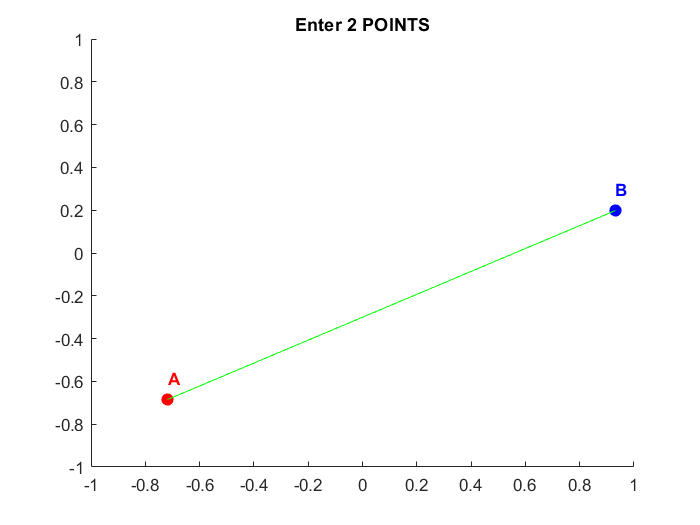

clf
axis([-1 1 -1 1])
title('Enter 2 POINTS')
hold on

A = ginput(1);
plot(A(1), A(2), '.r', 'MarkerSize', 25)
text(A(1), A(2) + .1, 'A', 'Color', 'r', 'FontWeight', 'bold');

B = ginput(1);
plot(B(1), B(2), '.b', 'MarkerSize', 25)
text(B(1), B(2) + .1, 'B', 'Color', 'b', 'FontWeight', 'bold');

plot([A(1), B(1)], [A(2), B(2)], 'g')
t=0:0.01:1;
S=(1-t)*A(1)+t*B(1); % Xi
S(2,:)=(1-t)*A(2)+t*B(2); % Yi
for n=1:size(S,2)
    h=plot(S(1,n),S(2,n),'.g','MarkerSize',20);
    axis([-1 1 -1 1])
    drawnow
    pause(.03)
    if(n~=1)||(n~=size(S,2))
        set(h,'Visible','Off')
        clear h
    end
end

## Задание 2.

Разработайте программу (m-сценарий), позволяющую пользователю задавать с помощью мыши два отрезка A и B, после чего выполните твининг отрезка A в отрезок B с отображением исходного отрезка A, целевого отрезка B и текущего промежуточного изображения (твина) между A и B при изменении параметра t от 0 до 1 с заданным шагом.

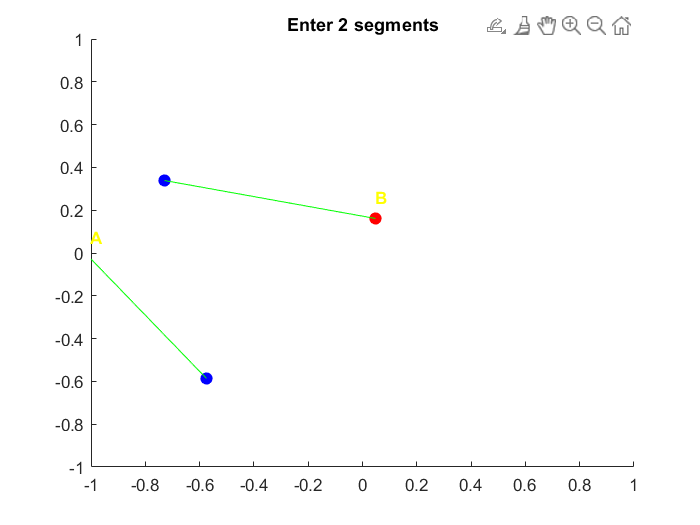

twin_2(0.01)

## Задание 1.

Разработайте программу (m-сценарий), позволяющую пользователю задавать с помощью мыши два отрезка A и B, после чего отобразите исходный отрезок A, целевой отрезок B и все промежуточные изображения (твины) между A и B при изменении параметра t от 0 до 1 с заданным шагом.

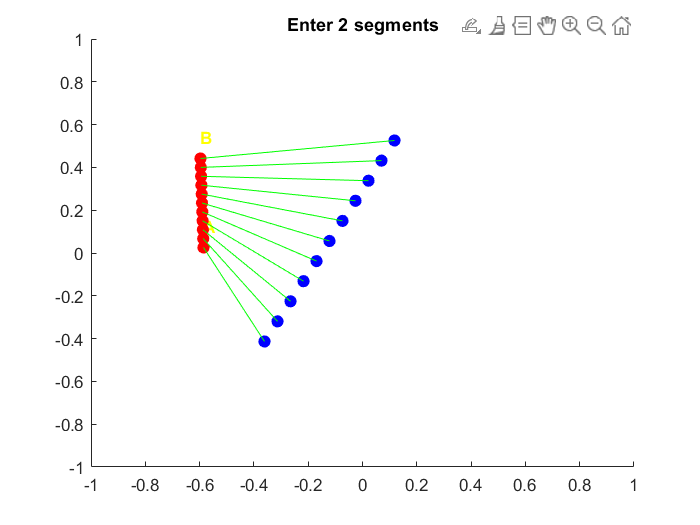

twin_1(0.1)

## Задание 3.

Разработайте программу (m-сценарий), позволяющую пользователю задавать с помощью мыши два отрезка A и B, после чего отобразите исходный отрезок A, целевой отрезок B и все промежуточные изображения (твины) между A и B при изменении параметра t от 0 до 1 с заданным шагом.

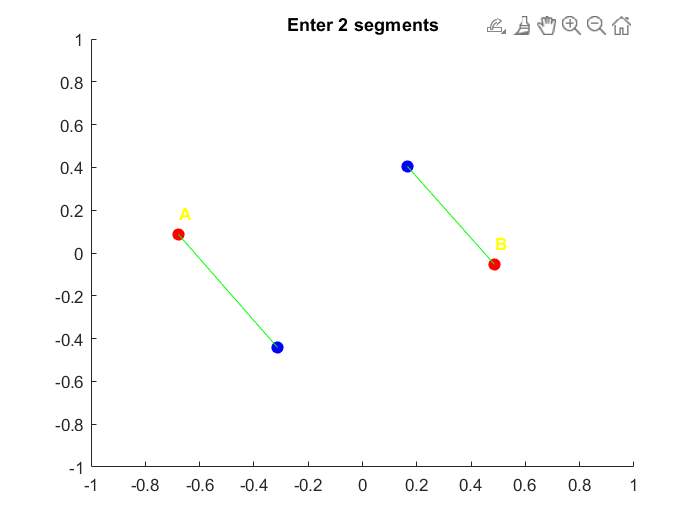

twin_3(0.01)

## Задание 4.

Разработайте программу (m-сценарий), позволяющую пользователю задавать с помощью мыши два отрезка A и B, после чего отобразите исходный отрезок A, целевой отрезок B и все промежуточные изображения (твины) между A и B при изменении параметра t от 0 до 1 с заданным шагом.

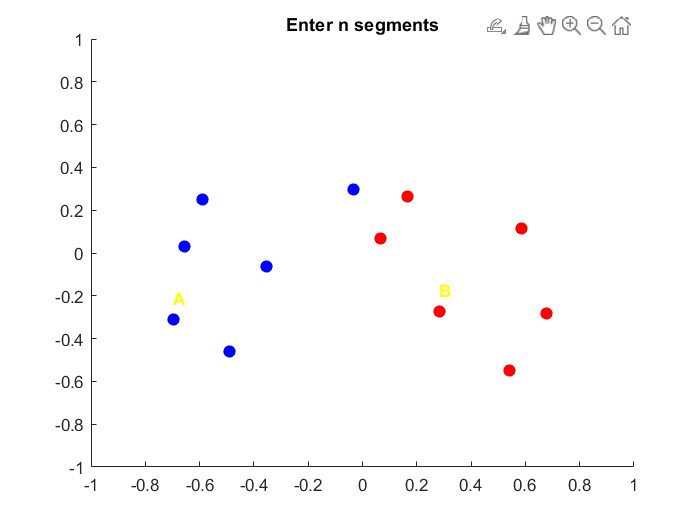

twin_4(6, 0.01)